## Demo: Illustrating 1/f and DFT

This demo illustrates some of the issues related to the typical 1/f shape of amplitude and power spectra obtained from neural time series. 

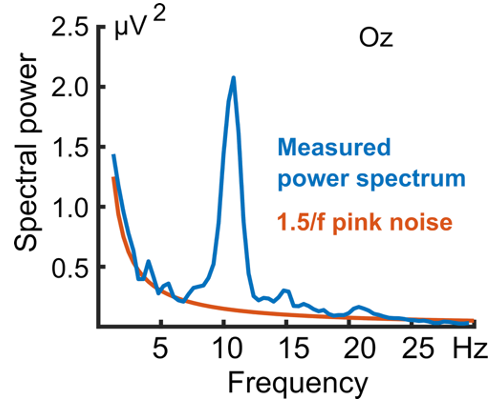

Figure 1. Example of the 1/f shape of an empirical EEG spectrum, with the best fitting exponential function shown in red. Note how the power in the alpha band range (around 10Hz) deviates from the 1/f shape. Figure from Keil et al. [https://doi.org/10.1111/psyp.14052](https://doi.org/10.1111/psyp.14052)

This shape (see figure above) is often modeled as an exponential function, characterized by higher amplitudes at lower frequencies and lower amplitudes at high frequencies (red line in figure above), and its presence in spectra creates some challenges for measuring and comparing spectral power/amplitude in neuroscience studies. We will look at how this shape may obscure signals that researchers may be interested in, but also how trial averaging, widely used in neuroscience impacts the effect of 1/f shape on detecting an oscillation. 

We start by making a discrete time vector, at which the signal will be sampled. 

clear
time = 0.001:0.001:1; % one second of discrete time
faxis = 0:500; % frequency axis goes from 0 to nyquist in steps of 1

... now we make 50 trials of white noise (stochastic) segments, the same noise to be used for all future simulations. We display the white noise along with each trial's frequency spectrum, and finally calculate the average spectrum which is expected to be flat in nature, not showing a 1/f shape. 

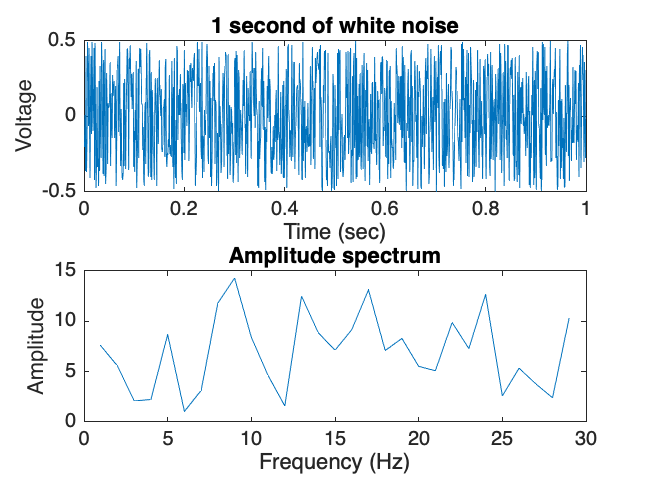

whitesig = rand(50,1000)-.5; % zero centered white noise

for trial = 1:50
    subplot(2,1,1), plot(time, whitesig(trial, :)), xlabel('Time (sec)'), ylabel('Voltage'), title('1 second of white noise')
    fftspec = fft(whitesig(trial, :)'); % calculate DFT
    sumspec(trial, :) = abs(fftspec); % save it for later
    subplot(2,1,2), plot(abs(fftspec (2:30))), xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Amplitude spectrum')
    pause(.2)

end

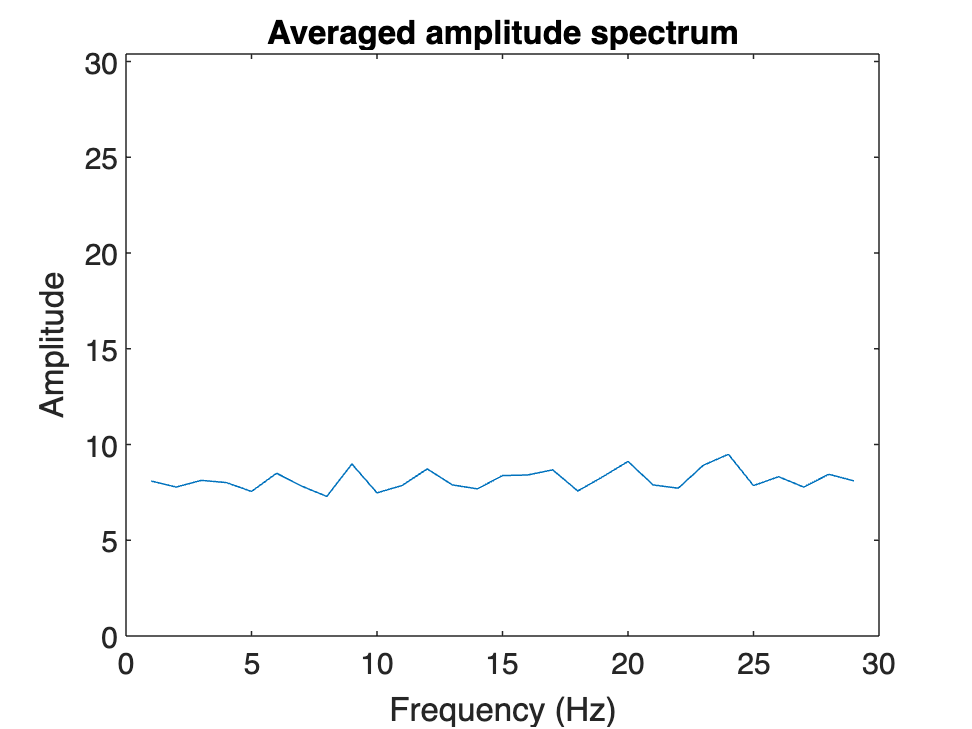


figure
plot(mean((sumspec(:, 2:30)))), axis([ 0 30 0 max(max(sumspec))])
xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectrum')

Next, we repeat that process with the cumulative sum of the white noise, which results in brownian noise. The spectrum of brownian noise is expected to have a 1/f shape, characteristic fro biological (including neural) systems. 

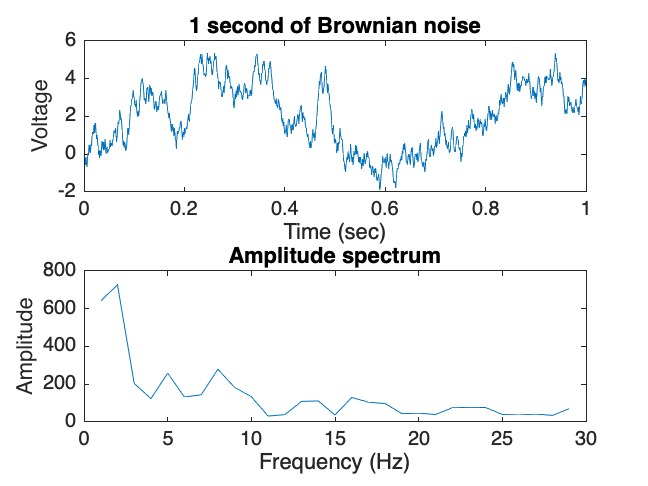

for trial = 1:50
    brownsig(trial,:) = cumsum(whitesig(trial, :));
    subplot(2,1,1), plot(time, brownsig(trial,:)), xlabel('Time (sec)'), ylabel('Voltage'), title('1 second of Brownian noise')
    fftspec = fft(brownsig(trial,:)); % calculate DFT
    sumspec(trial, :) = abs(fftspec); % save it for later
    subplot(2,1,2), plot(abs(fftspec (2:30))), xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Amplitude spectrum')
    pause(.2)
end

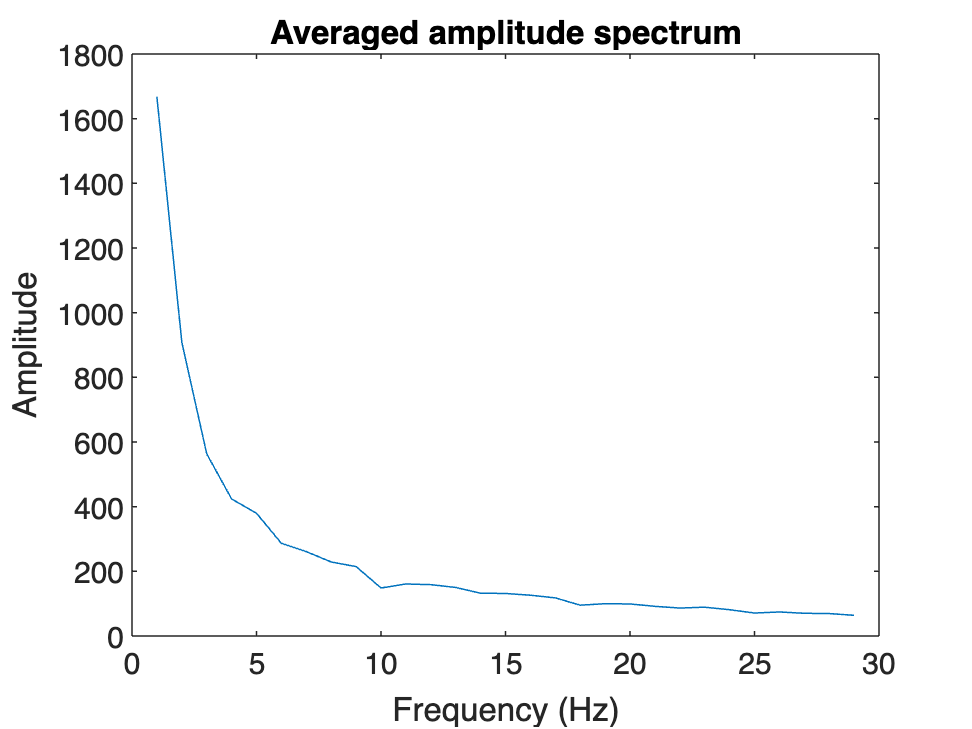


figure
plot(mean((sumspec(:, 2:30))))
xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectrum')

now we add a variable alpha oscillation to each trial

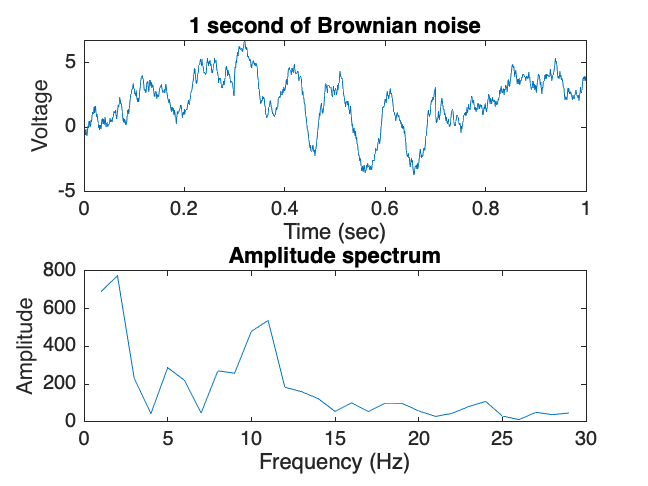


for trial = 1:50
    brownsig(trial,:) = cumsum(whitesig(trial, :));
    alphasig = sin(2*pi*time*(8+rand(1,1).*3)).*3;
    brownsig(trial, 300:700) = brownsig(trial, 300:700) + alphasig(300:700); 
    subplot(2,1,1), plot(time, brownsig(trial,:)), xlabel('Time (sec)'), ylabel('Voltage'), title('1 second of Brownian noise')
    fftspec = fft(brownsig(trial,:)); % calculate DFT
    sumspec(trial, :) = abs(fftspec); % save it for later
    subplot(2,1,2), plot(abs(fftspec (2:30))), xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Amplitude spectrum')
    pause(.2)

end

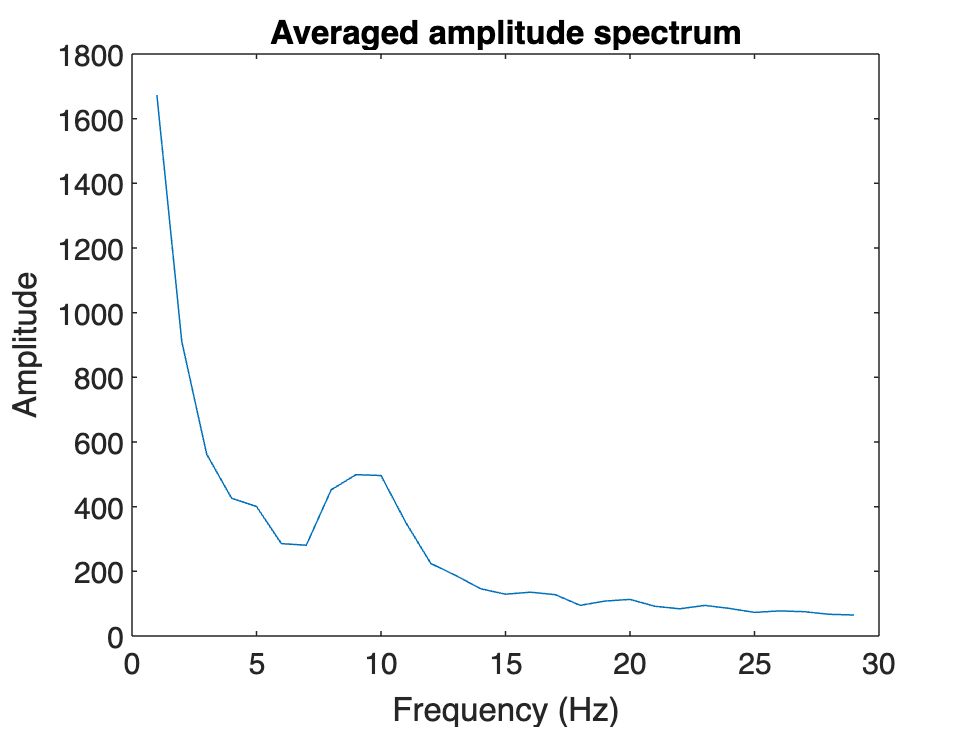


figure
plot(mean((sumspec(:, 2:30))))
xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectrum')

Same, but we do 10 runs and look at the variability across runs after averaging 50 trials 

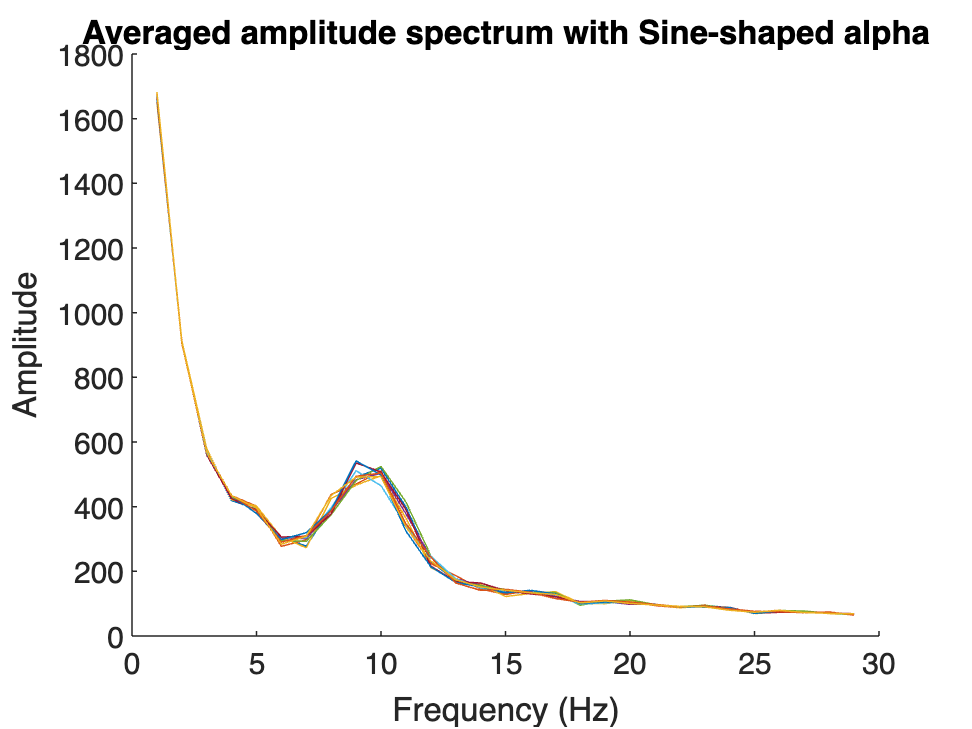

figure, hold on

for run = 1:10
  for trial = 1:50
    brownsig(trial,:) = cumsum(whitesig(trial, :));
    alphasig = sin(2*pi*time*(8+rand(1,1).*3)).*3;
    brownsig(trial, 300:700) = brownsig(trial, 300:700) + alphasig(300:700); 
    fftspec = fft(brownsig(trial,:)); % calculate DFT
    sumspecsine(trial, :) = abs(fftspec); % save it for later
  end

  plot(mean((sumspecsine(:, 2:30))))
  xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectrum with Sine-shaped alpha')
end
hold off

Same, but we do 10 runs with SAWTOOTH instead of sine-shaped akpha and look at the variability across runs after averaging 50 trials 

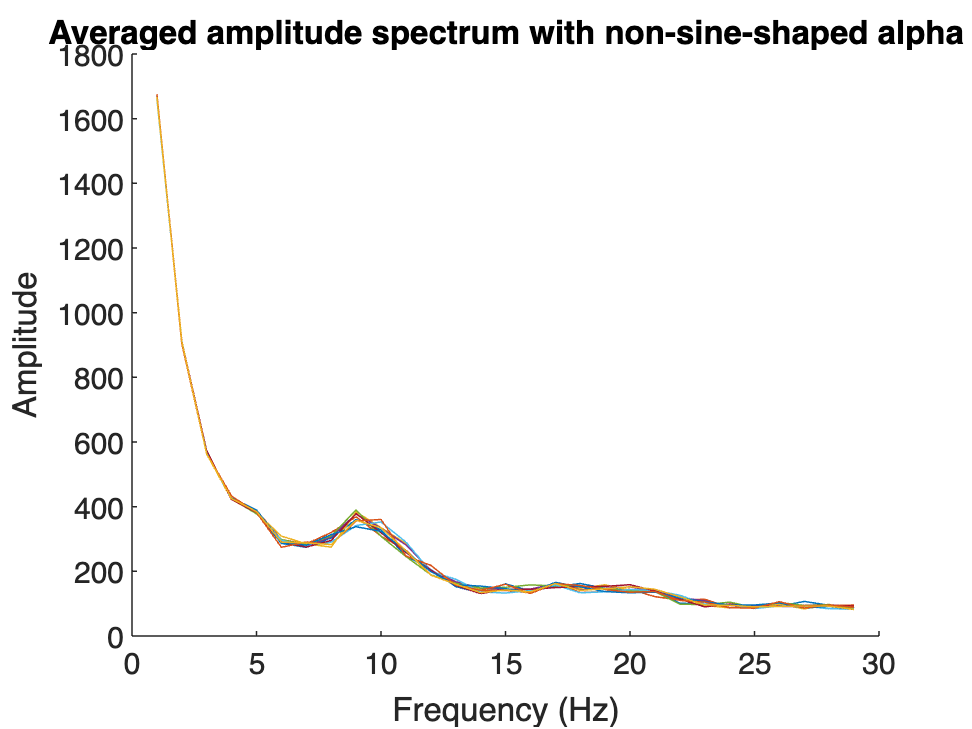

figure, hold on

for run = 1:10
  for trial = 1:50
    brownsig(trial,:) = cumsum(whitesig(trial, :));
    alphasig = sawtooth(2*pi*time*(8+rand(1,1).*3)).*3;
    brownsig(trial, 300:700) = brownsig(trial, 300:700) + alphasig(300:700); 
    fftspec = fft(brownsig(trial,:)); % calculate DFT
    sumspec(trial, :) = abs(fftspec); % save it for later
  end

  plot(mean((sumspec(:, 2:30))))
  xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectrum with non-sine-shaped alpha')
end
hold off

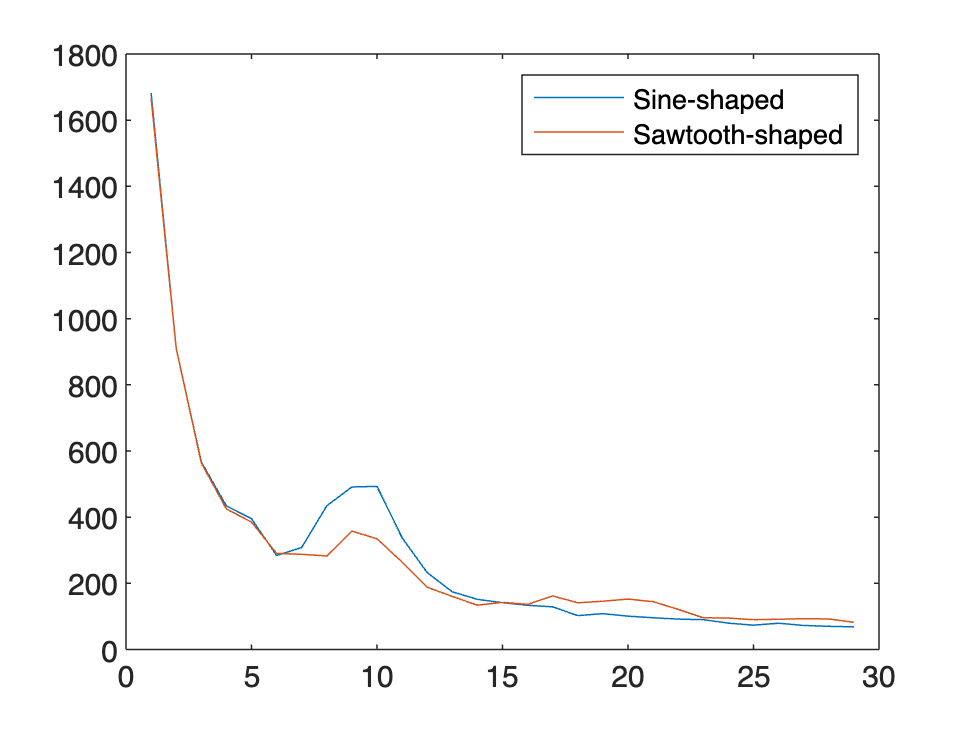


figure
  plot(mean((sumspecsine(:, 2:30))))
  hold on 
  plot(mean((sumspec(:, 2:30))))
  legend('Sine-shaped', 'Sawtooth-shaped')

Let's make a dent into the 1/f shape

for trial = 1:50

    brownsig(trial,:) = cumsum(whitesig(trial, :))-mean(cumsum(whitesig(trial, :)));
    %subplot(2,1,1), plot(time, brownsig(trial,:)), xlabel('Time (sec)'), ylabel('Voltage'), title('1 second of Brownian noise')
    fftspec = fft(brownsig(trial,:)); % calculate DFT
    sumspec(trial, :) = abs(fftspec); % save it for later
    %subplot(2,1,2), plot(abs(fftspec (2:30))), xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Amplitude spectrum')

end

figure
plot(faxis(2:30), mean((sumspec(:, 2:30))))
xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectrum')
hold on

% change the gain
for trial = 1:50

    brownsig(trial,:) = cumsum(whitesig(trial, :).*2)-mean(cumsum(whitesig(trial, :).*2));
    %subplot(2,1,1), plot(time, brownsig(trial,:)), xlabel('Time (sec)'), ylabel('Voltage'), title('1 second of Brownian noise')
    fftspec = fft(brownsig(trial,:)); % calculate DFT
    sumspec(trial, :) = abs(fftspec); % save it for later
    %subplot(2,1,2), plot(abs(fftspec (2:30))), xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Amplitude spectrum')

end

plot(faxis(2:30),mean((sumspec(:, 2:30))))
xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectrum')
hold on